# Principal Component Analysis

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads and displays the data.

T = readtable("./data/pumpFeatures.csv")

T = 1000×85 table
    wMotor_mean    wMotor_std    wMotor_fftPeakIdx    wMotor_skewness    wMotor_kurtosis    wMotor_peak2peak    wMotor_peak2rms    wMotor_rms    wMotor_mad    wMotor_csRange    wMotor_pLow    wMotor_pMid    wMotor_pHigh    wMotor_pKur    iMotor_mean    iMotor_std    iMotor_fftPeakIdx    iMotor_skewness    iMotor_kurtosis    iMotor_peak2peak    iMotor_peak2rms    iMotor_rms    iMotor_mad    iMotor_csRange    iMotor_pLow    iMotor_pMid    iMotor_pHigh    iMotor_pKur    qIn_mean    

This code fits a 10-fold cross-validated Naive Bayes model to the original data and calculates the loss.

rng(1)
mdlOrig = fitcnb(T, "faultCode", "KFold", 10);
kfoldLoss(mdlOrig)

ans = 0.1870

## Task 1

To perform PCA, you need to standardize your data so that all variables have the same standard deviation. You can do this using the `zscore` function.

`normData` `=` `zscore``(``rawData``)` 

T{:, 1:end-1} = zscore(T{:, 1:end-1});

## Task 2

You can use the `pca` function to get transformed data and the percent variance explained by each principal component.

`[``~,``tfmData``,~,~,``pctExp``]` `=` `pca``(``rawData``)`

[pcs, scrs, ~, ~, pexp] = pca(T{:, 1:end-1});

## Task 3

You can use the `pareto` function to visualize the variance explained by the principle components.

`pareto``(``pctExp``)`

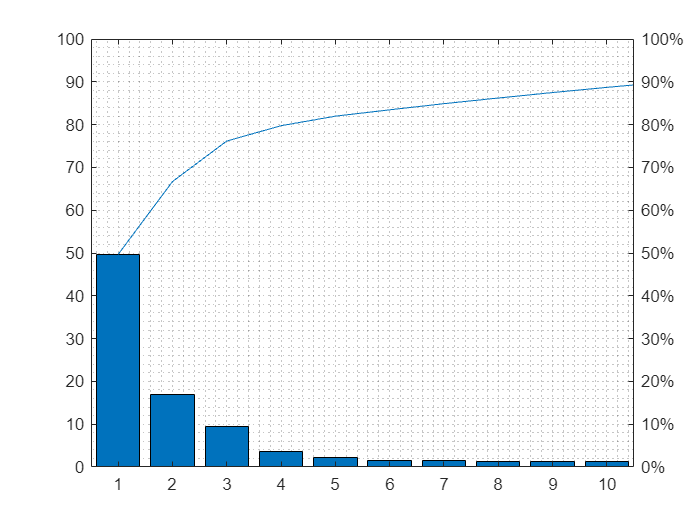

pareto(pexp)
grid minor

## Task 4

The Pareto chart shows that the first ten principal components explain approximately 90% of the variance. How many principal components do we need to explain at least 99% of the variance?

pos = find(cumsum(pexp) >= 99, 1)

pos = 28

## Task 5

The first 28 principal components explain more than 99% of the variance.

PCApreds = scrs(:, 1:pos);

## Task 6

mdl = fitcnb(PCApreds, T.faultCode, "KFold", 10);
mdlLoss = kfoldLoss(mdl)

mdlLoss = 0.2840